# DFA on acoustic features

Playing around with all experimental dates manually checked so far

BaseDataDir = '/Volumes/server_home/users/JulieE/DeafSalineGroup151/';
BaseCodeDir = '/Users/elie/Documents/CODE/GitHub/';

Loading previous data

load(fullfile(BaseDataDir, 'Data4_DeafBats_CatCalls.mat'))
MicAudioGood = logical(MicAudioGood);

Get color vectors ready

% Get the color vector ready for call type
ColorCode = [get(groot, 'DefaultAxesColorOrder'); 0 1 1; 0.5 0.5 0.5; 1 0 0 ; 0 1 0 ; 0 0 1; 0 0 0];
UCT = unique(CallType);
UCTFull = UCT;
UCTFull{strcmp(UCT, 'Tr')} = 'Trill';
UCTFull{strcmp(UCT, 'Ba')} = 'Bark';
UCTFull{strcmp(UCT, 'Pi')} = 'Pitchy Call';
UCTFull{strcmp(UCT, 'Bu')} = 'Low Buzz';
UCTFull{strcmp(UCT, 'Pa')} = 'Panting';
UCTFull{strcmp(UCT, 'LT')} = 'Low Tuck';
UCTFull{strcmp(UCT, 'Sq')} = 'Squeal';
UCTFull{strcmp(UCT, 'Ra')} = 'Rattle';
UCTFull{strcmp(UCT, 'Ch')} = 'Chuckles';
UCTFull{strcmp(UCT, 'BB')} = 'Bark Buzz';
UCTFull{strcmp(UCT, 'PB')} = 'Pitchy Call Buzz';
UCTFull{strcmp(UCT, 'SB')} = 'Squeal Buzz';
UCTFull{strcmp(UCT, 'Un')} = 'Unknown';
CCT = nan(length(CallType),3);
for ct=1:length(UCT)
    CCT(contains(CallType,UCT(ct)),:) = repmat(ColorCode(ct,:),sum(contains(CallType,UCT(ct))),1);
end

% Get the color vector ready for Batname
UBat = unique(BatID);
CBat = nan(length(BatID),3);
for bat=1:length(UBat)
    CBat(contains(BatID,UBat(bat)),:) = repmat(ColorCode(bat,:),sum(contains(BatID,UBat(bat))),1);
end

% Get the color vector ready for Sex and Deafness
Path2RecordingTable = '/Volumes/GoogleDrive/My Drive/JuvenileRecordings/DeafRecordingsNWAF155_Log.xlsx';
[~,~,RecTableData]=xlsread(Path2RecordingTable,2,'A1:k3','basic');
BatName = cell2mat(RecTableData(3,2:11));
BatSexDeaf = cell(length(BatName),1);
CSexDeaf =  nan(length(BatID),3);
SexDeaf =  cell(length(BatID),1);
Sex =  cell(length(BatID),1);
Deaf = cell(length(BatID),1);
for bat = 1:length(BatName)
    ColID = 1+ bat;
    if strcmp(RecTableData(1,ColID), 'K') && strcmp(RecTableData(2,ColID), 'M')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(1,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'DM'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'M'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'D'};
        BatSexDeaf{bat} = 'Deaf Male';
    elseif strcmp(RecTableData(1,ColID), 'S') && strcmp(RecTableData(2,ColID), 'M')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(6,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'HM'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'M'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'H'};
        BatSexDeaf{bat} = 'Hearing Male';
    elseif strcmp(RecTableData(1,ColID), 'S') && strcmp(RecTableData(2,ColID), 'F')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(3,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'HF'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'F'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'H'};
        BatSexDeaf{bat} = 'Hearing Female';
    elseif strcmp(RecTableData(1,ColID), 'K') && strcmp(RecTableData(2,ColID), 'F')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(2,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'DF'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'F'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'D'};
        BatSexDeaf{bat} = 'Deaf Female';
    end

end
USexDeaf = {'Deaf Male' 'Hearing Male' 'Deaf Female' 'Hearing Female'};
UCSexDeaf = ColorCode([1 6 2 3], :);

% AcousticClusters = nan(size(Deaf));
% AcousticClusters(strcmp(Deaf, 'D')) = TD;
% AcousticClusters(strcmp(Deaf, 'H')) = T;
AcousticClusters = TAll;

Construct the table of PAF for statistical purposes

Tbl =  table(BatID, CallType, Sex,AcousticClusters,Deaf,log10(Duration),RMS_mean,Sal_mean,F0_mean,Spect_mean,Spect_std,Spect_kurt,Spect_skew,Spect_ent,...
    Time_mean,Time_std,Time_kurt,Time_skew,Time_ent,SpectralMean_mean,Q1_mean,Q2_mean,Q3_mean,SpectMic_mean,SpectMic_std,...
    SpectMic_kurt,SpectMic_skew,SpectMic_ent,Q1Mic_mean,Q2Mic_mean,Q3Mic_mean, 'VariableNames', {'BatID', 'CT','Sex','AcousticClusters','HorD',...
    'Duration','RMS_mean','Sal_mean','F0_mean','Spect_mean','Spect_std','Spect_kurt','Spect_skew','Spect_ent',...
    'Time_mean','Time_std','Time_kurt','Time_skew','Time_ent','SpectralMean_mean','Q1_mean','Q2_mean','Q3_mean','SpectMic_mean','SpectMic_std',...
    'SpectMic_kurt','SpectMic_skew','SpectMic_ent','Q1Mic_mean','Q2Mic_mean','Q3Mic_mean'});
Tbl.HorD = categorical(Tbl.HorD, {'H' 'D'});
Tbl.AcousticClusters = categorical(Tbl.AcousticClusters);

## DFA approach

See how well we can classify pairs of bats in each acoustic cluster based on all acoustic features normalized by sex. The hypothesis is that the performance of classification should be higher for Deaf - Hearing pairs than for Hearing-hearing and Deaf-Deaf pairs.

Loop through the different Acoustic categories

% Acoustic cluster list
UCat = unique(AcousticClusters);
% Pairs of bats
C = nchoosek(1:length(BatName),2);
% Output probability of correct discrimination
PCC = nan(length(UCat),size(C,1));
for Cat = 1:length(UCat)
    % normalize the Acoustic features values according to sex using the
    % mean and std over individul mean values
    AcVar_pBat = nan(length(BatName),length(AcVars));
    for bb=1:length(BatName)
        Ind = logical(strcmp(Tbl.BatID,num2str(BatName(bb))) .* (double(Tbl.AcousticClusters)==UCat(Cat)));
        AcVar_pBat(bb,:) = mean(Tbl(Ind,6:end).Variables,1, 'omitnan');
    end
    MeanAcVarM = mean(AcVar_pBat(contains(BatSexDeaf, 'Male'),:),1);
    StdAcVarM = std(AcVar_pBat(contains(BatSexDeaf, 'Male'),:),[],1);
    MeanAcVarF = mean(AcVar_pBat(contains(BatSexDeaf, 'Female'),:),1);
    StdAcVarF = std(AcVar_pBat(contains(BatSexDeaf, 'Female'),:),[],1);

    Tbl_norm = Tbl(double(Tbl.AcousticClusters)==UCat(Cat),:);
    for bb=1:length(BatName)
        Ind = find(strcmp(Tbl_norm.BatID,num2str(BatName(bb))));
        if strcmp(Tbl_norm.Sex(Ind(1)),'M')
            for ii=1:length(Ind)
                Tbl_norm(Ind(ii),6:end).Variables = (Tbl_norm(Ind(ii),6:end).Variables-MeanAcVarM)./StdAcVarM;
            end
        elseif strcmp(Tbl_norm.Sex(Ind(1)),'F')
            for ii=1:length(Ind)
                Tbl_norm(Ind(ii),6:end).Variables = (Tbl_norm(Ind(ii),6:end).Variables-MeanAcVarF)./StdAcVarF;
            end
        end
    end

    % loop through pairs of bats train a DFA on subset of the data and
    % calculate the performance in crossvalidation (leave one out scheme to
    % accomodate for the different numbers of calls for each bat)
    
    PairType = cell(size(C,1),1);
    for pp = 1:size(C,1)
        fprintf(1, 'Bat Pair: %d  --  %d\n', BatName(C(pp,1)), BatName(C(pp,2)))
        PairType{pp} = [BatSexDeaf{C(pp,1)}(1) BatSexDeaf{C(pp,2)}(1)];
        Tbl4DFA = [Tbl_norm(strcmp(Tbl_norm.BatID, num2str(BatName(C(pp,1)))), [1 6:end]); Tbl_norm(strcmp(Tbl_norm.BatID, num2str(BatName(C(pp,2)))), [1 6:end])];
        % remove data of Mic features when Audio is not of good quality
        AudioGood_local = [MicAudioGood(strcmp(Tbl_norm.BatID, num2str(BatName(C(pp,1))))); MicAudioGood(strcmp(Tbl_norm.BatID, num2str(BatName(C(pp,2)))))];
        Indcc = find(contains(Tbl4DFA.Properties.VariableNames, 'Mic'));
        for cc=1:length(Indcc)
            Tbl4DFA(~AudioGood_local,Indcc(cc)).Variables = nan(sum(~AudioGood_local),1);
        end
        % perform a leave-one-out cross validation keeping the same number of
        % calls from both bats in all training set
        IndBat1 = find(strcmp(Tbl4DFA.BatID, num2str(BatName(C(pp,1)))));
        IndBat2 = find(strcmp(Tbl4DFA.BatID, num2str(BatName(C(pp,2)))));
        IndBat12 = [IndBat1; IndBat2];
        N1 = length(IndBat1);
        N2 = length(IndBat2);
        MinN = min(N1,N2)-1;
        if MinN<10 % not enough data to train the model 
            fprintf(1,'*** Not enough calls Bat1 %d, Bat2 %d', N1, N2)
            continue
        end
        Correct = nan(N1+N2,1);

        parfor kk=1:(N1+N2)%parfor
            % Train the data for that element
            IndBat1kT = IndBat1;
            if kk<=N1
                IndBat1kT(kk) = [];
            end
            IndBat1kT = IndBat1kT(randperm(length(IndBat1kT)));
            IndBat1kT = IndBat1kT(1:MinN);
            IndBat2kT = IndBat2;
            if kk>N1
                IndBat2kT(kk-N1) = [];
            end
            IndBat2kT = IndBat2kT(randperm(length(IndBat2kT)));
            IndBat2kT = IndBat2kT(1:MinN);
            
            MdlT = fitcdiscr(Tbl4DFA([IndBat1kT; IndBat2kT],:),'BatID','Prior', 'Uniform');
            % Predict on the held out kk fold data
            Label = predict(MdlT, Tbl4DFA(IndBat12(kk),:));
            Correct(kk) = strcmp(Label, Tbl4DFA.BatID(IndBat12(kk)));
%             confusionchart(Tbl4DFA.BatID([IndBat1kP; IndBat2kP]),Labels)
%             Loss(kk) = loss(MdlT, Tbl4DFA([IndBat1kP; IndBat2kP],:), Tbl4DFA.BatID([IndBat1kP; IndBat2kP]),'LossFun', 'mincost');
        end
        PCC(Cat,pp) = sum(Correct)/(N1+N2);
    end
end

Bat Pair: 14463  --  71354


Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).


Bat Pair: 14463  --  71047
Bat Pair: 14463  --  65696
Bat Pair: 14463  --  11648
Bat Pair: 14463  --  71353
Bat Pair: 14463  --  71351
Bat Pair: 14463  --  14461
Bat Pair: 14463  --  14464
Bat Pair: 14463  --  71043
Bat Pair: 71354  --  71047
Bat Pair: 71354  --  65696
Bat Pair: 71354  --  11648
Bat Pair: 71354  --  71353
Bat Pair: 71354  --  71351
Bat Pair: 71354  --  14461
Bat Pair: 71354  --  14464
Bat Pair: 71354  --  71043
Bat Pair: 71047  --  65696
Bat Pair: 71047  --  11648
Bat Pair: 71047  --  71353
Bat Pair: 71047  --  71351
Bat Pair: 71047  --  14461
Bat Pair: 71047  --  14464
Bat Pair: 71047  --  71043
Bat Pair: 65696  --  11648
Bat Pair: 65696  --  71353
Bat Pair: 65696  --  71351
Bat Pair: 65696  --  14461
Bat Pair: 65696  --  14464
Bat Pair: 65696  --  71043
Bat Pair: 11648  --  71353
Bat Pair: 11648  --  71351
Bat Pair: 11648  --  14461
Bat Pair: 11648  --  14464
Bat Pair: 11648  --  71043
Bat Pair: 71353  --  71351
Bat Pair: 71353  --  14461
Bat Pair: 71353  --  14464
B

*** Not enough calls Bat1 218, Bat2 10

Bat Pair: 14463  --  71047
Bat Pair: 14463  --  65696
Bat Pair: 14463  --  11648
Bat Pair: 14463  --  71353
Bat Pair: 14463  --  71351
Bat Pair: 14463  --  14461
Bat Pair: 14463  --  14464
Bat Pair: 14463  --  71043
Bat Pair: 71354  --  71047


*** Not enough calls Bat1 10, Bat2 25

Bat Pair: 71354  --  65696


*** Not enough calls Bat1 10, Bat2 321

Bat Pair: 71354  --  11648


*** Not enough calls Bat1 10, Bat2 23

Bat Pair: 71354  --  71353


*** Not enough calls Bat1 10, Bat2 65

Bat Pair: 71354  --  71351


*** Not enough calls Bat1 10, Bat2 34

Bat Pair: 71354  --  14461


*** Not enough calls Bat1 10, Bat2 43

Bat Pair: 71354  --  14464


*** Not enough calls Bat1 10, Bat2 68

Bat Pair: 71354  --  71043


*** Not enough calls Bat1 10, Bat2 36

Bat Pair: 71047  --  65696
Bat Pair: 71047  --  11648
Bat Pair: 71047  --  71353
Bat Pair: 71047  --  71351
Bat Pair: 71047  --  14461
Bat Pair: 71047  --  14464
Bat Pair: 71047  --  71043
Bat Pair: 65696  --  11648
Bat Pair: 65696  --  71353
Bat Pair: 65696  --  71351
Bat Pair: 65696  --  14461
Bat Pair: 65696  --  14464
Bat Pair: 65696  --  71043
Bat Pair: 11648  --  71353
Bat Pair: 11648  --  71351
Bat Pair: 11648  --  14461
Bat Pair: 11648  --  14464
Bat Pair: 11648  --  71043
Bat Pair: 71353  --  71351
Bat Pair: 71353  --  14461
Bat Pair: 71353  --  14464
Bat Pair: 71353  --  71043
Bat Pair: 71351  --  14461
Bat Pair: 71351  --  14464
Bat Pair: 71351  --  71043
Bat Pair: 14461  --  14464
Bat Pair: 14461  --  71043
Bat Pair: 14464  --  71043
Bat Pair: 14463  --  71354
Bat Pair: 14463  --  71047
Bat Pair: 14463  --  65696
Bat Pair: 14463  --  11648
Bat Pair: 14463  --  71353
Bat Pair: 14463  --  71351
Bat Pair: 14463  --  14461
Bat Pair: 14463  --  14464
Bat Pair: 14463  --  71043
B

*** Not enough calls Bat1 300, Bat2 6

Bat Pair: 14463  --  71353
Bat Pair: 14463  --  71351
Bat Pair: 14463  --  14461
Bat Pair: 14463  --  14464
Bat Pair: 14463  --  71043
Bat Pair: 71354  --  71047
Bat Pair: 71354  --  65696
Bat Pair: 71354  --  11648


*** Not enough calls Bat1 46, Bat2 6

Bat Pair: 71354  --  71353
Bat Pair: 71354  --  71351
Bat Pair: 71354  --  14461
Bat Pair: 71354  --  14464
Bat Pair: 71354  --  71043
Bat Pair: 71047  --  65696
Bat Pair: 71047  --  11648


*** Not enough calls Bat1 169, Bat2 6

Bat Pair: 71047  --  71353
Bat Pair: 71047  --  71351
Bat Pair: 71047  --  14461
Bat Pair: 71047  --  14464
Bat Pair: 71047  --  71043
Bat Pair: 65696  --  11648


*** Not enough calls Bat1 68, Bat2 6

Bat Pair: 65696  --  71353
Bat Pair: 65696  --  71351
Bat Pair: 65696  --  14461
Bat Pair: 65696  --  14464
Bat Pair: 65696  --  71043
Bat Pair: 11648  --  71353


*** Not enough calls Bat1 6, Bat2 78

Bat Pair: 11648  --  71351


*** Not enough calls Bat1 6, Bat2 65

Bat Pair: 11648  --  14461


*** Not enough calls Bat1 6, Bat2 46

Bat Pair: 11648  --  14464


*** Not enough calls Bat1 6, Bat2 32

Bat Pair: 11648  --  71043


*** Not enough calls Bat1 6, Bat2 39

Bat Pair: 71353  --  71351
Bat Pair: 71353  --  14461
Bat Pair: 71353  --  14464
Bat Pair: 71353  --  71043
Bat Pair: 71351  --  14461
Bat Pair: 71351  --  14464
Bat Pair: 71351  --  71043
Bat Pair: 14461  --  14464
Bat Pair: 14461  --  71043
Bat Pair: 14464  --  71043
Bat Pair: 14463  --  71354


*** Not enough calls Bat1 18, Bat2 5

Bat Pair: 14463  --  71047
Bat Pair: 14463  --  65696


*** Not enough calls Bat1 18, Bat2 9

Bat Pair: 14463  --  11648
Bat Pair: 14463  --  71353


*** Not enough calls Bat1 18, Bat2 3

Bat Pair: 14463  --  71351
Bat Pair: 14463  --  14461
Bat Pair: 14463  --  14464
Bat Pair: 14463  --  71043
Bat Pair: 71354  --  71047


*** Not enough calls Bat1 5, Bat2 18

Bat Pair: 71354  --  65696


*** Not enough calls Bat1 5, Bat2 9

Bat Pair: 71354  --  11648


*** Not enough calls Bat1 5, Bat2 13

Bat Pair: 71354  --  71353


*** Not enough calls Bat1 5, Bat2 3

Bat Pair: 71354  --  71351


*** Not enough calls Bat1 5, Bat2 32

Bat Pair: 71354  --  14461


*** Not enough calls Bat1 5, Bat2 95

Bat Pair: 71354  --  14464


*** Not enough calls Bat1 5, Bat2 26

Bat Pair: 71354  --  71043


*** Not enough calls Bat1 5, Bat2 208

Bat Pair: 71047  --  65696


*** Not enough calls Bat1 18, Bat2 9

Bat Pair: 71047  --  11648
Bat Pair: 71047  --  71353


*** Not enough calls Bat1 18, Bat2 3

Bat Pair: 71047  --  71351
Bat Pair: 71047  --  14461
Bat Pair: 71047  --  14464
Bat Pair: 71047  --  71043
Bat Pair: 65696  --  11648


*** Not enough calls Bat1 9, Bat2 13

Bat Pair: 65696  --  71353


*** Not enough calls Bat1 9, Bat2 3

Bat Pair: 65696  --  71351


*** Not enough calls Bat1 9, Bat2 32

Bat Pair: 65696  --  14461


*** Not enough calls Bat1 9, Bat2 95

Bat Pair: 65696  --  14464


*** Not enough calls Bat1 9, Bat2 26

Bat Pair: 65696  --  71043


*** Not enough calls Bat1 9, Bat2 208

Bat Pair: 11648  --  71353


*** Not enough calls Bat1 13, Bat2 3

Bat Pair: 11648  --  71351
Bat Pair: 11648  --  14461
Bat Pair: 11648  --  14464
Bat Pair: 11648  --  71043
Bat Pair: 71353  --  71351


*** Not enough calls Bat1 3, Bat2 32

Bat Pair: 71353  --  14461


*** Not enough calls Bat1 3, Bat2 95

Bat Pair: 71353  --  14464


*** Not enough calls Bat1 3, Bat2 26

Bat Pair: 71353  --  71043


*** Not enough calls Bat1 3, Bat2 208

Bat Pair: 71351  --  14461
Bat Pair: 71351  --  14464
Bat Pair: 71351  --  71043
Bat Pair: 14461  --  14464
Bat Pair: 14461  --  71043
Bat Pair: 14464  --  71043
Bat Pair: 14463  --  71354


*** Not enough calls Bat1 13, Bat2 9

Bat Pair: 14463  --  71047


*** Not enough calls Bat1 13, Bat2 2

Bat Pair: 14463  --  65696


*** Not enough calls Bat1 13, Bat2 7

Bat Pair: 14463  --  11648


*** Not enough calls Bat1 13, Bat2 2

Bat Pair: 14463  --  71353


*** Not enough calls Bat1 13, Bat2 6

Bat Pair: 14463  --  71351
Bat Pair: 14463  --  14461


*** Not enough calls Bat1 13, Bat2 9

Bat Pair: 14463  --  14464
Bat Pair: 14463  --  71043
Bat Pair: 71354  --  71047


*** Not enough calls Bat1 9, Bat2 2

Bat Pair: 71354  --  65696


*** Not enough calls Bat1 9, Bat2 7

Bat Pair: 71354  --  11648


*** Not enough calls Bat1 9, Bat2 2

Bat Pair: 71354  --  71353


*** Not enough calls Bat1 9, Bat2 6

Bat Pair: 71354  --  71351


*** Not enough calls Bat1 9, Bat2 113

Bat Pair: 71354  --  14461


*** Not enough calls Bat1 9, Bat2 9

Bat Pair: 71354  --  14464


*** Not enough calls Bat1 9, Bat2 88

Bat Pair: 71354  --  71043


*** Not enough calls Bat1 9, Bat2 98

Bat Pair: 71047  --  65696


*** Not enough calls Bat1 2, Bat2 7

Bat Pair: 71047  --  11648


*** Not enough calls Bat1 2, Bat2 2

Bat Pair: 71047  --  71353


*** Not enough calls Bat1 2, Bat2 6

Bat Pair: 71047  --  71351


*** Not enough calls Bat1 2, Bat2 113

Bat Pair: 71047  --  14461


*** Not enough calls Bat1 2, Bat2 9

Bat Pair: 71047  --  14464


*** Not enough calls Bat1 2, Bat2 88

Bat Pair: 71047  --  71043


*** Not enough calls Bat1 2, Bat2 98

Bat Pair: 65696  --  11648


*** Not enough calls Bat1 7, Bat2 2

Bat Pair: 65696  --  71353


*** Not enough calls Bat1 7, Bat2 6

Bat Pair: 65696  --  71351


*** Not enough calls Bat1 7, Bat2 113

Bat Pair: 65696  --  14461


*** Not enough calls Bat1 7, Bat2 9

Bat Pair: 65696  --  14464


*** Not enough calls Bat1 7, Bat2 88

Bat Pair: 65696  --  71043


*** Not enough calls Bat1 7, Bat2 98

Bat Pair: 11648  --  71353


*** Not enough calls Bat1 2, Bat2 6

Bat Pair: 11648  --  71351


*** Not enough calls Bat1 2, Bat2 113

Bat Pair: 11648  --  14461


*** Not enough calls Bat1 2, Bat2 9

Bat Pair: 11648  --  14464


*** Not enough calls Bat1 2, Bat2 88

Bat Pair: 11648  --  71043


*** Not enough calls Bat1 2, Bat2 98

Bat Pair: 71353  --  71351


*** Not enough calls Bat1 6, Bat2 113

Bat Pair: 71353  --  14461


*** Not enough calls Bat1 6, Bat2 9

Bat Pair: 71353  --  14464


*** Not enough calls Bat1 6, Bat2 88

Bat Pair: 71353  --  71043


*** Not enough calls Bat1 6, Bat2 98

Bat Pair: 71351  --  14461


*** Not enough calls Bat1 113, Bat2 9

Bat Pair: 71351  --  14464
Bat Pair: 71351  --  71043
Bat Pair: 14461  --  14464


*** Not enough calls Bat1 9, Bat2 88

Bat Pair: 14461  --  71043


*** Not enough calls Bat1 9, Bat2 98

Bat Pair: 14464  --  71043


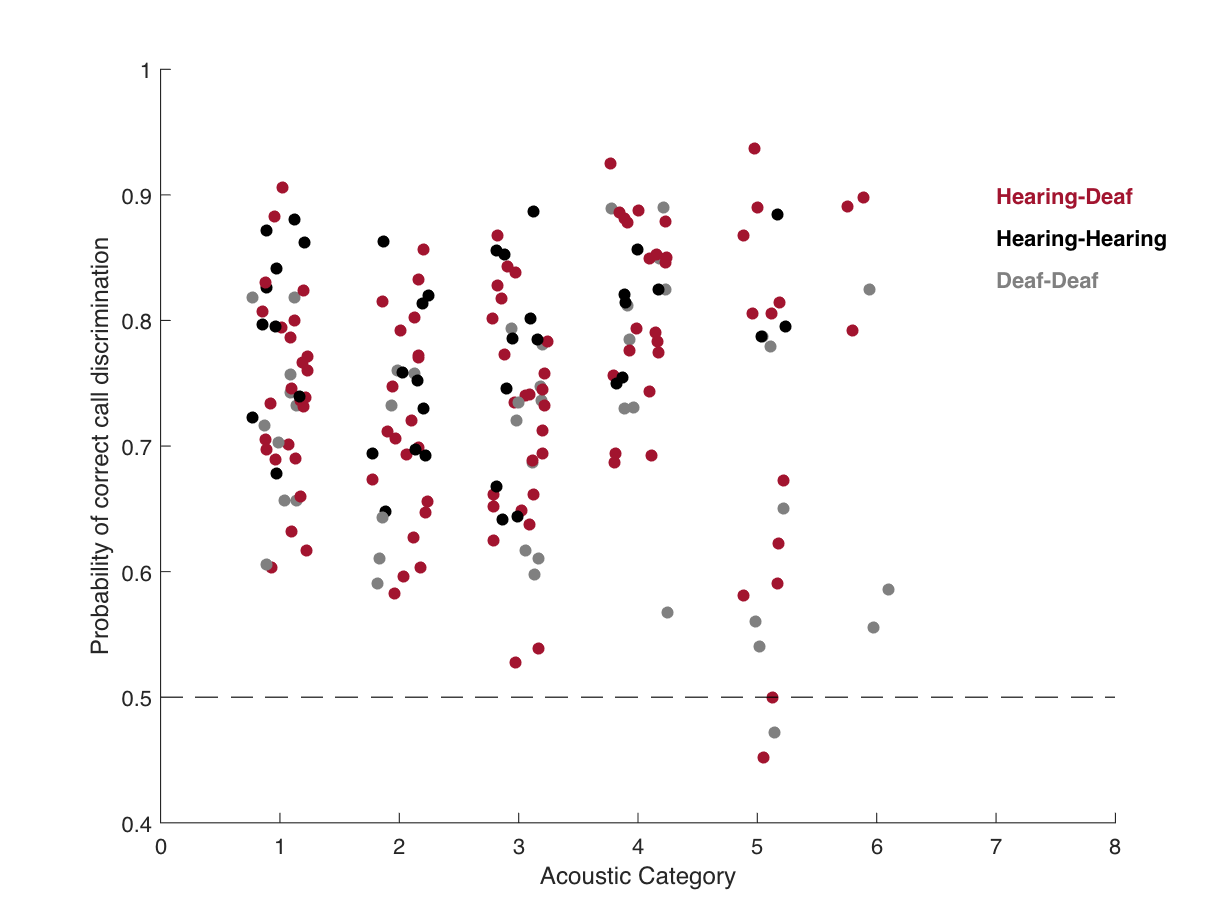

figure()
for pp=1:length(PairType)
    if strcmp(PairType{pp}, 'DH') || strcmp(PairType{pp}, 'HD')
        Color = ColorCode(7,:);
    elseif strcmp(PairType{pp}, 'HH')
        Color = 'k';
    elseif strcmp(PairType{pp}, 'DD')
        Color = 0.5.*ones(1,3);
    end
    scatter((1:length(UCat))' + (rand(length(UCat),1)-0.5)*0.5, PCC(:,pp),30, Color,'filled')
    hold on
end
text((length(UCat)+1), 1-3/30, 'Hearing-Deaf', 'Color',ColorCode(7,:), 'FontWeight','bold')
hold on
text((length(UCat)+1), 1-4/30, 'Hearing-Hearing', 'Color','k', 'FontWeight','bold')
hold on
text((length(UCat)+1), 1-5/30, 'Deaf-Deaf', 'Color',0.5.*ones(1,3), 'FontWeight','bold')
hold on

xlabel('Acoustic Category')
ylabel('Probability of correct call discrimination')
xlim([0 length(UCat)+2])
ylim([0.4 1])
hline(0.5,'k--')
hold off

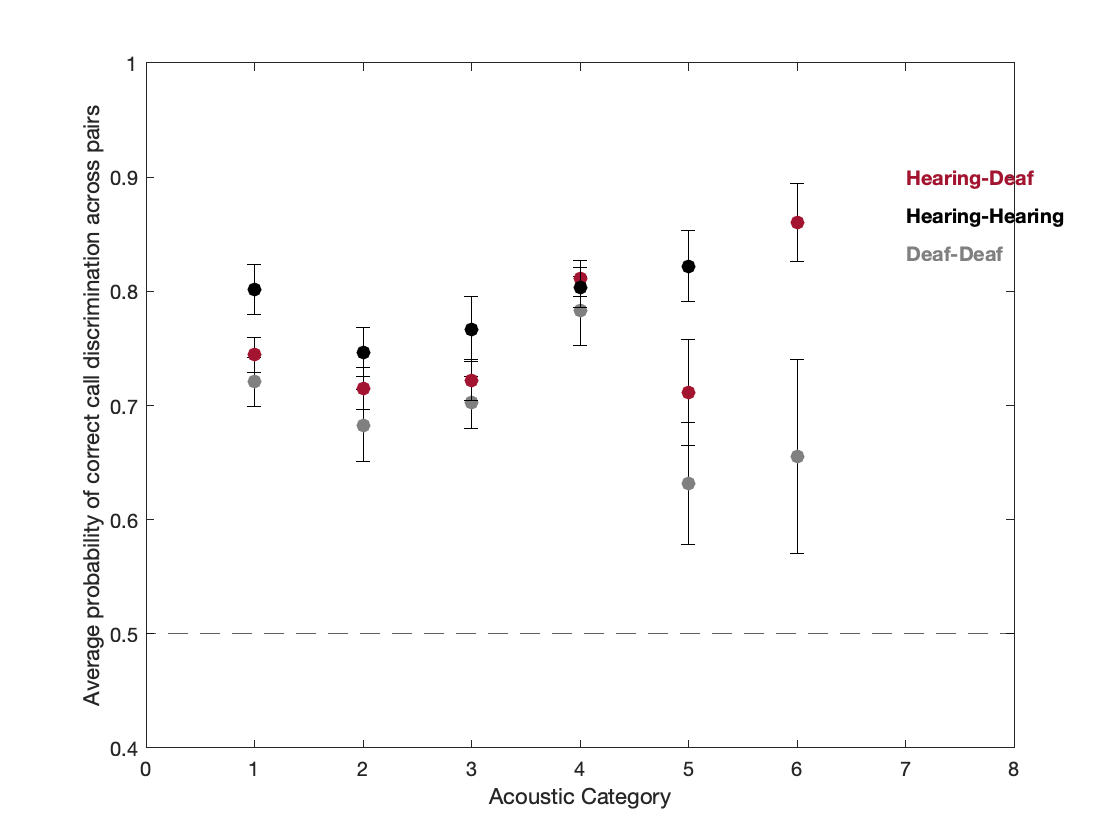

PairType2= PairType;
PairType2(strcmp(PairType2,'DH')) = {'HD'};
UPairType = unique(PairType2);
MeanPCC = nan(length(UPairType), length(UCat));
SEPCC = nan(length(UPairType), length(UCat));
figure()

for pp=1:length(UPairType)
    MeanPCC(pp,:) = mean(PCC(:,strcmp(PairType2, UPairType{pp})),2, 'omitnan')';
    STDPCC = std(PCC(:,strcmp(PairType2, UPairType{pp})),[],2, 'omitnan')';
    NumObs = sum(~isnan(PCC(:,strcmp(PairType2, UPairType{pp}))),2);
    SEPCC(pp,:) = STDPCC./NumObs'.^0.5;

    if strcmp(UPairType{pp}, 'HD')
        Color = ColorCode(7,:);
    elseif strcmp(UPairType{pp}, 'HH')
        Color = 'k';
    elseif strcmp(UPairType{pp}, 'DD')
        Color = 0.5.*ones(1,3);
    end
    errorbar(1:length(UCat), MeanPCC(pp,:),SEPCC(pp,:),SEPCC(pp,:),[],[],'k.')
    hold on
    scatter(1:length(UCat), MeanPCC(pp,:),50, Color,'filled')
    hold on
end
text((length(UCat)+1), 1-3/30, 'Hearing-Deaf', 'Color',ColorCode(7,:), 'FontWeight','bold')
hold on
text((length(UCat)+1), 1-4/30, 'Hearing-Hearing', 'Color','k', 'FontWeight','bold')
hold on
text((length(UCat)+1), 1-5/30, 'Deaf-Deaf', 'Color',0.5.*ones(1,3), 'FontWeight','bold')
hold on

xlabel('Acoustic Category')
ylabel('Average probability of correct call discrimination across pairs')
xlim([0 length(UCat)+2])
ylim([0.4 1])
hline(0.5,'k--')
hold off

Conclusion: there is as much info in vocalizations to discriminate between individuals as there is to discriminate between Deaf and Hearing individuals. The hearing status of the bat pair is not making the discrimination easier.

## DFA approach 2

See how well we can classify calls from bats as either deaf or hearing in each acoustic cluster based on all acoustic features normalized by sex. Here we follow a leave one individual out for cross-validation.

Loop through the different Acoustic categories

% Acoustic cluster list
UCat = unique(AcousticClusters);

% Output probability of correct classification of each individual's calls
PCC_HorD = nan(length(UCat),length(BatName));
NumCalls = PCC_HorD;
for Cat = 1:length(UCat)
    % normalize the Acoustic features values according to sex using the
    % mean and std over individul mean values
    AcVar_pBat = nan(length(BatName),length(AcVars));
    for bb=1:length(BatName)
        Ind = logical(strcmp(Tbl.BatID,num2str(BatName(bb))) .* (double(Tbl.AcousticClusters)==UCat(Cat)));
        AcVar_pBat(bb,:) = mean(Tbl(Ind,6:end).Variables,1, 'omitnan');
    end
    MeanAcVarM = mean(AcVar_pBat(contains(BatSexDeaf, 'Male'),:),1);
    StdAcVarM = std(AcVar_pBat(contains(BatSexDeaf, 'Male'),:),[],1);
    MeanAcVarF = mean(AcVar_pBat(contains(BatSexDeaf, 'Female'),:),1);
    StdAcVarF = std(AcVar_pBat(contains(BatSexDeaf, 'Female'),:),[],1);

    Tbl_norm = Tbl(double(Tbl.AcousticClusters)==UCat(Cat),:);
    for bb=1:length(BatName)
        Ind = find(strcmp(Tbl_norm.BatID,num2str(BatName(bb))));
        if strcmp(Tbl_norm.Sex(Ind(1)),'M')
            for ii=1:length(Ind)
                Tbl_norm(Ind(ii),6:end).Variables = (Tbl_norm(Ind(ii),6:end).Variables-MeanAcVarM)./StdAcVarM;
            end
        elseif strcmp(Tbl_norm.Sex(Ind(1)),'F')
            for ii=1:length(Ind)
                Tbl_norm(Ind(ii),6:end).Variables = (Tbl_norm(Ind(ii),6:end).Variables-MeanAcVarF)./StdAcVarF;
            end
        end
    end

    % remove data of Mic features when Audio is not of good quality
    MicAudioGood_local =MicAudioGood(double(Tbl.AcousticClusters)==UCat(Cat));
    Indcc = find(contains(Tbl_norm.Properties.VariableNames, 'Mic'));
    for cc=1:length(Indcc)
        Tbl_norm(~MicAudioGood_local,Indcc(cc)).Variables = nan(sum(~MicAudioGood_local),1);
    end
    

    % loop through individual bats, setting each as a testing set, training a DFA on the rest of the data and
    % calculate the performance in crossvalidation (leave one out bat
    % scheme). In the training data we want to make sure we take the same
    % number of calls from all bats, with a minimum of 10 calls
%%%% Maybe change the cross validation method here??    
    for pp = 1:length(BatName)
        fprintf(1, 'Bat: %d\n', BatName(pp))
        IndBatT = find(~strcmp(Tbl_norm.BatID, num2str(BatName(pp))));
        IndBatP = find(strcmp(Tbl_norm.BatID, num2str(BatName(pp))));
        NumCalls(Cat,pp) = length(IndBatP);
        if length(IndBatT) < 5*size(Tbl4DFAT,2) % we need at least 5 points of data per estimated coefficients
            fprintf(1, 'Not enough vocalizations from that bat\n')
            continue
        end
        Tbl4DFAT = Tbl_norm(IndBatT, 5:end);
        Tbl4DFAP = Tbl_norm(IndBatP, 5:end);
        
        MdlT = fitcdiscr(Tbl4DFAT,'HorD','Prior', 'Uniform');
        
        % Predict on the held out individual calls
        Label = predict(MdlT, Tbl4DFAP);
        Correct = Label==Tbl4DFAP.HorD;
%             confusionchart(Tbl4DFAP.HorD,Labels)
%             Loss = loss(MdlT, Tbl4DFAP, Tbl4DFAP.HorD,'LossFun', 'mincost');
        PCC_HorD(Cat,pp) = sum(Correct)/length(Correct);
    end
end

Bat: 14463
Bat: 71354
Bat: 71047
Bat: 65696
Bat: 11648
Bat: 71353
Bat: 71351
Bat: 14461
Bat: 14464
Bat: 71043
Bat: 14463
Bat: 71354
Bat: 71047
Bat: 65696
Bat: 11648
Bat: 71353
Bat: 71351
Bat: 14461
Bat: 14464
Bat: 71043
Bat: 14463
Bat: 71354
Bat: 71047
Bat: 65696
Bat: 11648
Bat: 71353
Bat: 71351
Bat: 14461
Bat: 14464
Bat: 71043
Bat: 14463
Bat: 71354
Bat: 71047
Bat: 65696
Bat: 11648
Bat: 71353
Bat: 71351
Bat: 14461
Bat: 14464
Bat: 71043
Bat: 14463
Bat: 71354
Bat: 71047
Bat: 65696
Bat: 11648
Bat: 71353
Bat: 71351
Bat: 14461
Bat: 14464
Bat: 71043
Bat: 14463
Bat: 71354
Bat: 71047
Bat: 65696
Bat: 11648
Bat: 71353
Bat: 71351
Bat: 14461
Bat: 14464
Bat: 71043


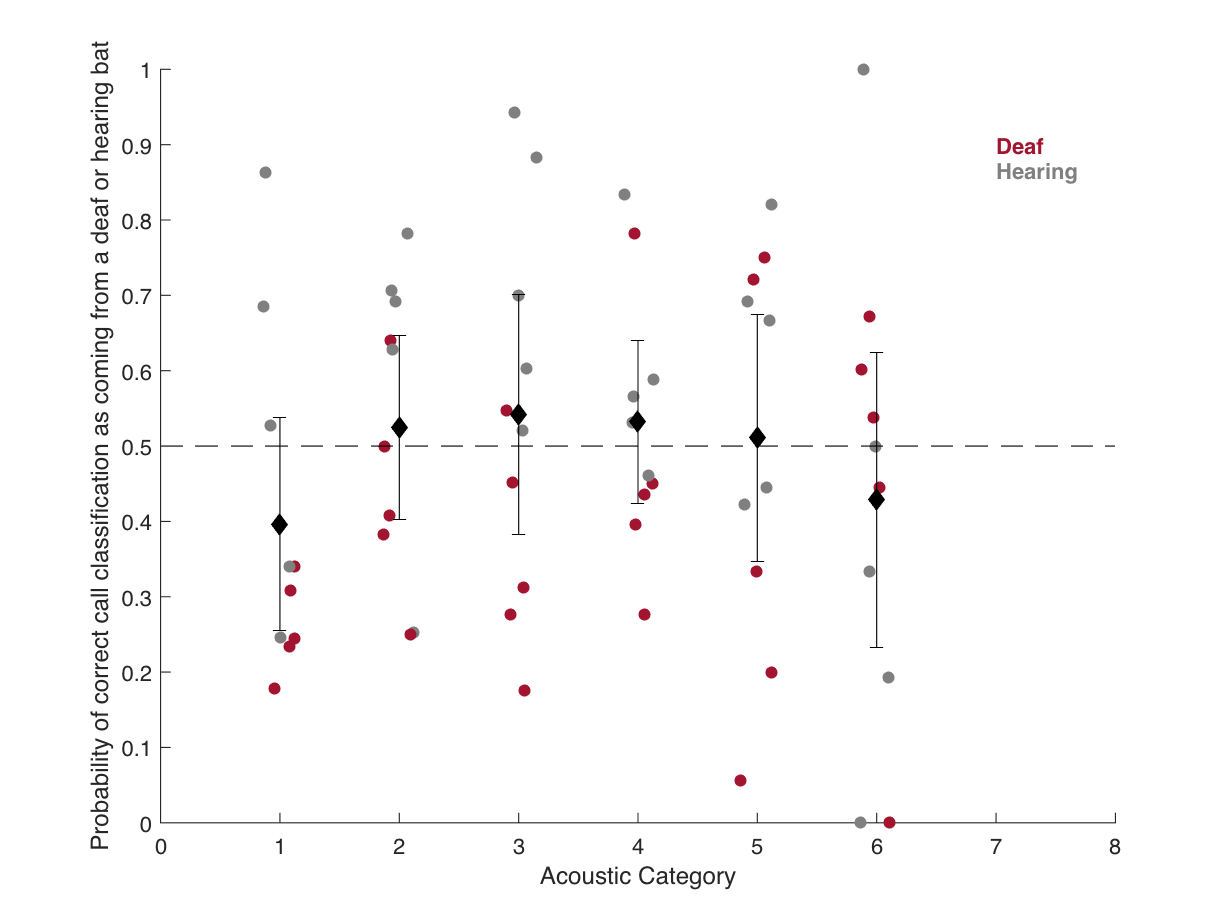

figure()
for pp=1:length(BatName)
    if contains(BatSexDeaf{pp}, 'Deaf')
        Color = ColorCode(7,:);
    elseif contains(BatSexDeaf{pp}, 'Hearing')
        Color = [0.5 0.5 0.5];
    end
    scatter((1:length(UCat))' + (rand(length(UCat),1)-0.5)*0.3, PCC_HorD(:,pp),30, Color,'filled')
    hold on
end
text((length(UCat)+1), 1-3/30, 'Deaf', 'Color',ColorCode(7,:), 'FontWeight','bold')
hold on
text((length(UCat)+1), 1-4/30, 'Hearing', 'Color',[0.5 0.5 0.5], 'FontWeight','bold')
hold on
MeanPCC_HorD = mean(PCC_HorD,2);
SEPCC_HorD = std(PCC_HorD,[],2)./sum(~isnan(PCC_HorD),2).^0.5;
errorbar((1:length(UCat))', MeanPCC_HorD, 2*SEPCC_HorD,2*SEPCC_HorD,'.k');
hold on
scatter((1:length(UCat))', MeanPCC_HorD,50,'dk','filled')
hold off
xlabel('Acoustic Category')
ylabel('Probability of correct call classification as coming from a deaf or hearing bat')
xlim([0 length(UCat)+2])
% ylim([0.4 1])
hline(0.5,'k--')
hold off

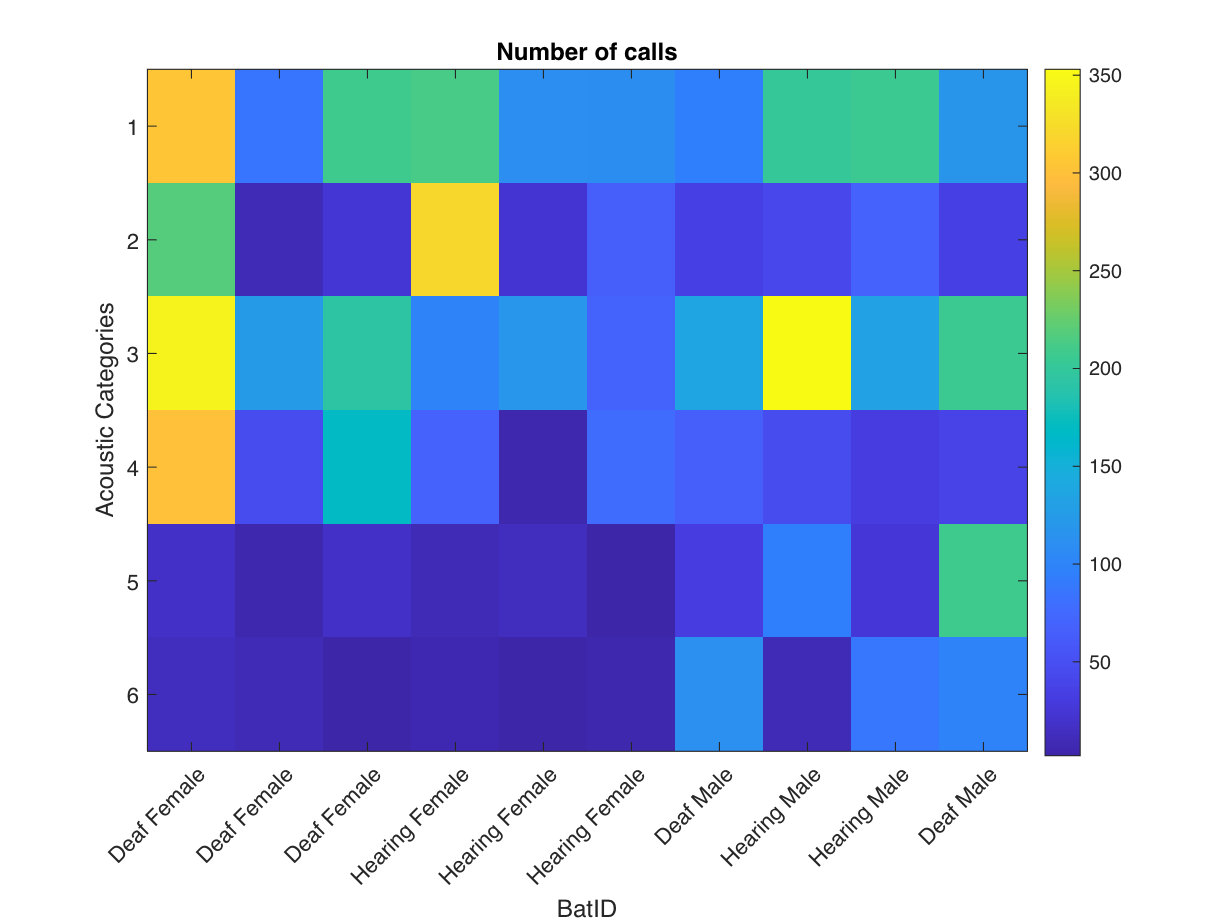

IM = imagesc(NumCalls);
xlabel('BatID')
ylabel('Acoustic Categories')
colorbar()
title('Number of calls')
IM.Parent.XTick = 1:length(BatName);
IM.Parent.XTickLabels=BatSexDeaf;
IM.Parent.XTickLabelRotation = 45;